# Clog Loss: Advance Alzheimer’s Research with Stall Catchers

### **Team AZ_KA: Azin Al Kajbaf, Kaveh Faraji Najarkolaie**

## **Step2. The main procedure for classification of vessels**

In this section, the main approach that is used for classifying the videos is explained. We have also implemented other approaches which will be explained in summary, however, due to the limitation of the GPU that we had access to, we were bound to use these alternative methods in the most simplified way. However, with higher GPU power and customizing those methods, it might be possible to obtain better results from them, too. 

At first, we tried approaches that are mostly used in human action recognition. However, after a while we tried an approach that in our opinion was simple, faster and more suitable to the nature of the videos for recognizing stalled and flowing vessels. The approaches that we used are:

-  First, we used the [benchmark code](https://www.drivendata.co/blog/stall-catchers-alzheimers-benchmark/) approach which involved extracting the features with pre-trained network and then using Long Short-Term Memory (LSTM) network for predicting the labels. We used different options and [different pretrained deep neural network](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html) and we also developed a bigger training set than [Nano and Micro](https://www.drivendata.org/competitions/65/clog-loss-alzheimers-research/page/217/). These changes improved the score. After that, we used [opticalFlow](https://www.mathworks.com/help/vision/ref/opticalflowobject.html) object to obtain pixel velocity magnitudes image. We used these along with previous data as an input for LSTM network, however, we could not improve the result. We  also explored other ways of combining Convolutional Neural Network (CNN) and LSTM network (other than the benchmark code method), but we were not able to improve the score. 

-  The second approach that we used was converting videos to 3D images and using 3D CNN for classifying. We tried simple networks with few numbers of [convolution3dLayer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution3dlayer.html), but the score was not improved in the way that we used 3D CNN.

- The last approach that we used, which gave us the highest score, was converting the videos to combination of images and using transfer learning. The details of this approach are discussed in next paragraph and is also depicted in **Figure 1**. 

The steps of our third approach are:  

- At first step, we tried to select a suitable set of input data from the training set which we thought might give us good results.

- For second step, we split videos to 4 equal groups of frames.

- In third step, we obtained the average of the pixels of frames in each group and used it as the representative of these frame in our training approach.

- Then we constructed a single image that consisted of mean of these groups of frames as shown in step 4 of **Figure 1**.

- Afterward, in the last step (step 5), we used deep neural network (with retraining [ResNet-18](https://www.mathworks.com/help/deeplearning/ref/resnet18.html) ) to classify testing videos as stalled or flowing.

It should be mentioned that the highest score that we obtained is based on retraining [ResNet-18](https://www.mathworks.com/help/deeplearning/ref/resnet18.html) on just 13990 selected video files from the main training dataset which consisted of 573050 videos.

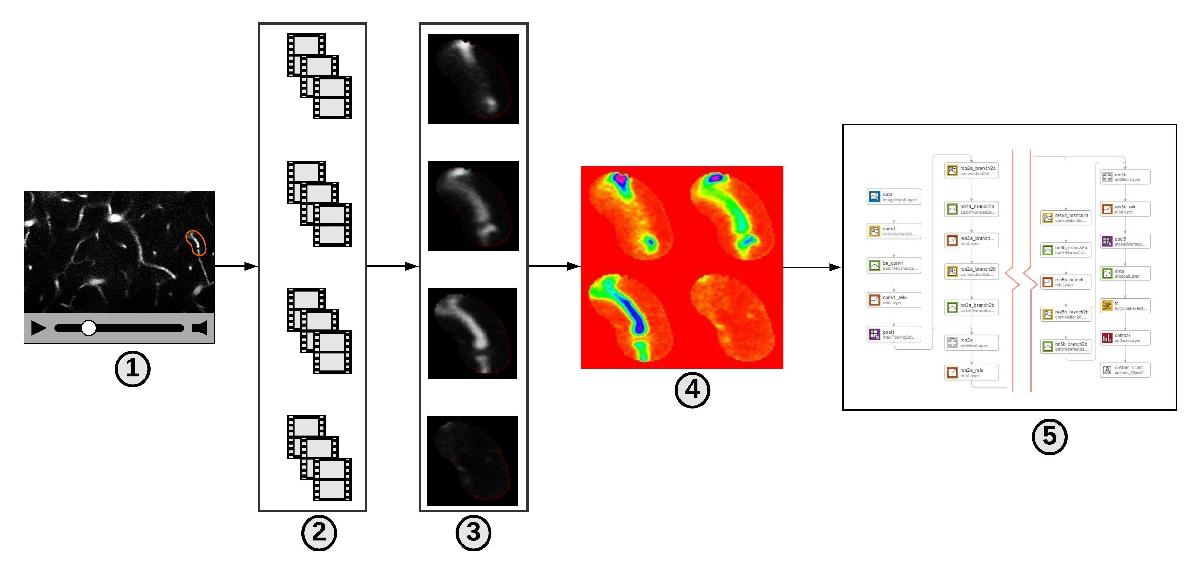

**Figure1**. Framework of our approach (video 101309.mp4 is used to create this figure)

For developing this code, [benchmark code](https://www.drivendata.co/blog/stall-catchers-alzheimers-benchmark/) for this competition is used in some places (especially the code was very helpful in processing the videos and cropping the Region of Interest (ROI) from main videos). In the next sections we included the code that gave us the highest score.

### 2.1. Load Training & Testing Data

To access the data from the file `train_metadata_V1.csv and train_labels.csv `load the file in the workspace.

clc;
clear;
train =readtable("train_metadata_V1.csv","TextType","string");
trainlabels = readtable("train_labels.csv");
test=readtable("test_metadata.csv");
trainlabels.stalled = categorical(trainlabels.stalled);

we used milli subset that we created in Step1 (file name: preparing_training_data.mlx).

milli_train = train(train.milli == 'True',:);
milli_trainlabels = trainlabels(train.milli == 'True',:);

### 2.2. Processing videos for Deep Learning

#### 2.2.1. Processing Training videos

In here we read and process training videos using helper functions readVideo and dectectROI at the end of this script. The original functions are provided by the benchmark code, however, we changed them based on the approach that we used.

% In here we used fileDatastore and helper functions for reading, processing and storing the training videos
datastorelocation='Datastore\';
millitrainadd='Input_train\';% provide location of selected training data
tempfds = fullfile(datastorelocation,"fds_milli.mat");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Using datastore for reading and storing videos location and file name
if exist(tempfds,'file')
	load(tempfds,'fds')
	files = fds.Files;
else
	fds = fileDatastore(millitrainadd,'ReadFcn', @readVideo);
	files = fds.Files;
	save(tempfds,"fds");
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Using helper function for processing the videos
% In here, a directory called 'Training_files' is created and two
% subdirectories which are representative of flowing (0) and 
% stalled (1) are also created.
if ~exist('Training_files',"dir")
	mkdir Training_files
	mkdir Training_files\0
	mkdir Training_files\1
	% Converting videos to an image with four tiles that each of them
	% represents average of pixels of 1/4 of all frames in the video
for ii=1:size(fds.Files,1)
		X=readVideo(fds.Files{ii});
		filename_temp{ii}=milli_trainlabels.filename{ii};
		filename{ii}=erase(filename_temp{ii},".mp4")+".jpg";
		if milli_trainlabels.stalled(ii)=='0'
			addr_name_0{ii}= fullfile("Training_files\0",filename{ii});
			imwrite(X,addr_name_0{ii});
		elseif milli_trainlabels.stalled(ii)=='1'
			addr_name_1{ii}= fullfile("Training_files\1",filename{ii});
			imwrite(X,addr_name_1{ii});
		end
	end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Creating ImageDatastore from processed training files
ImLoc = fullfile("Training_files\");
imds = imageDatastore(ImLoc, ...
    'FileExtensions','.jpg',"IncludeSubfolders",true,'LabelSource','foldernames');
% Dividing data to 90% training and 10% validation
rng(7)
[imdsTr, imdsVal]=splitEachLabel(imds,.9,"randomized");

#### 2.2.2. Processing testing videos

% In here we used fileDatastore and helper functions for reading, processing and storing the testing videos
datastorelocation='Datastore';
testadd='Input_test\';% Provide the location of the test set
tempfds_test = fullfile(datastorelocation,"fds_test.mat");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Using datastore for reading and storing videos location and file name
if exist(tempfds_test,'file')
	load(tempfds_test,'fds_test')
	files_test = fds_test.Files;
else
	fds_test = fileDatastore(testadd,'ReadFcn', @readVideo);
	files_test = fds_test.Files;
	save(tempfds_test,"fds_test");
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Using helper function for processing the videos
if ~exist('Testing_files',"dir")
	mkdir Testing_files
	for ii=1:size(fds_test.Files,1)
		X=readVideo(fds_test.Files{ii});
		filename=test.filename{ii};
		filename_temp=erase(filename,"Input_test\");
		filename=erase(filename_temp,".mp4")+".jpg";
		addr_name= fullfile("Testing_files\",filename);
		imwrite(X,addr_name);
	end
end

### 2.3. Load Pretrained CNN

To train the network we used a pretrained ResNet-18 model. Please install the ["Deep Learning Toolbox Model for ResNet-18 Network support package"](https://www.mathworks.com/help/deeplearning/ref/resnet18.html) before running this section.

netCNN = resnet18; 
cnnLayers = layerGraph(netCNN);
% Deleting three last layers
layerNames = ["fc1000" "prob" "ClassificationLayer_predictions"];
cnnLayers = removeLayers(cnnLayers,layerNames);

### 2.4. Preparing CNN

In here we created a CNN based on ResNet-18  that can classify the Images. A dropout layer, fullyconnected, softmax and classification layers are added and connected to the end of edited ResNet-18 network.

% We calculated the weight of each label to use it in the customized weighted loss function. 
labels = milli_trainlabels.stalled;
w=(imdsTr.Labels=='1');
w2=sum(w)/size(w,1);
w1=1-w2;
numClasses = 2;
layers1 = [dropoutLayer(0.1,'Name','drop')
	fullyConnectedLayer(numClasses,"Name","fc")
	softmaxLayer("Name","softmax")
	custom_ClassificationLayer([w2,w1],'custom_ClassificationLayer')];
lgraph = addLayers(cnnLayers,layers1);
lgraph = connectLayers(lgraph,"pool5","drop");
analyzeNetwork(lgraph);

### 2.5. Specify Training Options

We specified the training options using the trainingOptions function:

- Set a mini-batch size 32, an initial learning rate of 0.00015

- Shuffle the data every epoch.

- Validate the network once per epoch.

- Setting L2Regularization to 0.005

- Display the training progress in a plot and suppress verbose output.

- Stop the training when the preferred  accuracy (93%) is achieved

miniBatchSize = 32;
numObservations = numel(imdsTr.Files);
numIterationsPerEpoch = floor(numObservations / miniBatchSize);

options= trainingOptions('adam', ...
	'LearnRateSchedule','piecewise',...
	'LearnRateDropPeriod',10,...
	'LearnRateDropFactor',0.3,...
	'InitialLearnRate', 0.00015, ...     
	'MaxEpochs', 100,...              
	'MiniBatchSize', miniBatchSize, ...         
	'ValidationData',imdsVal, ...
	'ValidationFrequency',numIterationsPerEpoch, ...
	'Shuffle', "every-epoch" , ...
	'L2Regularization', 0.005,...
	'Verbose', true,...
	'Plots','training-progress', ...
	'OutputFcn',@(info)stopIfacc(info,93)); 

### 2.6. Train CNN

We then train the network using the trainNetwork function. 

train_ind=false; % If you want to train the CNN, change the value of "train_ind" to true
if train_ind==true
[net,info] = trainNetwork(imdsTr,lgraph,options);
%save('PreTrained.mat','net','info','options');
else
load("PreTrained_net.mat")
end

### 2.7. Predicting test files labels

In here, we used the trained network to predict labels of test files and create the submission file. 

% Return 
tic
folderTest = fullfile("Testing_files\");
Ds_Test = imageDatastore(folderTest);
YPred_test = classify(net,Ds_Test,'MiniBatchSize',miniBatchSize);
%YProb_test=predict(net,Ds_Test,'MiniBatchSize',miniBatchSize);
test = readtable("test_metadata.csv");
testResults = table(test.filename,YPred_test(:,1),'VariableNames',{'filename','stalled'});
writetable(testResults,'testResults.csv');
toc

Elapsed time is 21.077906 seconds.


### 2.8. Helper Functions

#### 2.8.1. Stop the training

We used this function to stop the training when the preferred accuracy is achieved.

function stop = stopIfacc(info,A)

stop = false;

% Clear the variables when training starts.
if info.State == "start"
	
elseif info.ValidationAccuracy>=A
	
	stop = true;
	
end

end

### 2.8.2. readVideo function

We used the benchmark code that was provided by MathWorks. The difference is that we divided the video's frames to 4 groups with the same number of frames. Then we found out the mean of pixels in each of those groups and converted each of these groups to a single image. Afterwards, we used the imtile function and combined those four images into a single 224X224X3 color image. 

Explanation about other parts of this function is provided by the [benchmark code](https://www.drivendata.co/blog/stall-catchers-alzheimers-benchmark/): "The `readVideo`function reads the video in `filename` and returns a cropped 4-D frame. The area of interest in the entire video is the orange colored area in each frame of the video which we would want to extract to use for the rest of our training. Hence, each frame is cropped as per the bounding box of the segment, calculated using the `detectROI` function."

It should be mentioned that sometimes, the readVideo function output does not capture the ROI correctly (or it captures it differently). Mostly this happens when we run this code on different computers, however, it also rarely happened when we used the same computer. Please observe **Figure.2** that shows the results of output of readVideo function on different computers. 

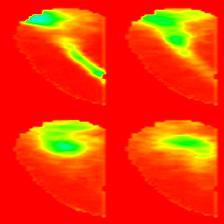     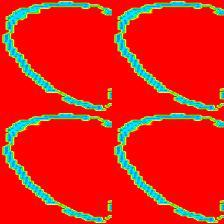     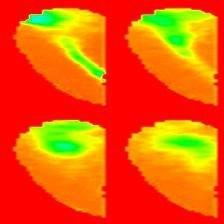   

**Figure2**. Output image of readVideo function on three different computers (video 100864.mp4 is used to create this figure)

function video2img = readVideo(filename)

vr = VideoReader(filename);
i = 0;

while hasFrame(vr)
	i = i+1;
	framein = readFrame(vr);
	if i < 2
		[Bbox, polymask] = detectROI(framein);
	end
	frame = bsxfun(@times, framein, cast(polymask,class(framein)));
	frame = imcrop(frame, Bbox);
	frame=imresize(frame,[224,224]);
	video(:,:,:,i)=frame;
end
num=floor(i/4);
for ii=1:4
	x=1+(ii-1)*num;
	y=ii*num;
	vidsection=video(:,:,:,x:y);
	% It was not neccessary to repeat imresize in this function,
	% but we did not change it since it was in the original code 
	vids{ii}=imresize(uint8(mean(vidsection,4)),[112 112]);
end
video2img=imtile({vids{1},vids{2},vids{3},vids{4}});
video2img=rgb2gray(video2img);
video2img= ind2rgb(video2img, hsv);
%imshow(video2img)
end

### 2.8.3. detectROI function

We changed the `detectROI`function provided by benchmark code so that it only considers the area inside the orange colored marker. The `detectROI`function provided by the benchmark code crops a rectangle which contains orange colored marker. We customized the code to mask the useless area outside the marker.

Explanation about this function is provided by the [benchmark code](https://www.drivendata.co/blog/stall-catchers-alzheimers-benchmark/): "The `detectROI`function, detects the outlined segment and thresholds the image based on `threshold` values  defined. This function is generated using MATLAB's [color thresholder app](https://www.mathworks.com/help/images/ref/colorthresholder-app.html). For detecting the area specified by the orange colured markers,  we used [Blob Analysis](https://in.mathworks.com/help/vision/ref/vision.blobanalysis-system-object.html). We chose to keep the area of interest as the blob with the largest major axis. Check out the following videos to learn more. "

function [Bbox, polymask] = detectROI(frameIn)

%% Setup the detector and initialize variables
persistent detector
if isempty(detector)
	detector = vision.BlobAnalysis('BoundingBoxOutputPort',true,'MajorAxisLengthOutputPort',true,...
		'LabelMatrixOutputPort',true );
end
%,'CentroidOutputPort',true
threshold = [104 255; 13 143; 9 98];

mask = (frameIn (:,:,1) >= threshold(1,1))& (frameIn (:,:,1) <= threshold(1,2))&...
	(frameIn (:,:,2) >= threshold(2,1))& (frameIn (:,:,2) <= threshold(2,2))&...
	(frameIn (:,:,3) >= threshold(3,1))& (frameIn (:,:,3) <= threshold(3,2));

[~, ~, Bbox1, majorAxis,Labels_R] = detector(mask);
logpic=imbinarize(Labels_R);
boundary = bwboundaries(logpic);
[~, max_index] = max(cellfun('size', boundary, 1));
mask=[boundary{max_index}(:,2) boundary{max_index}(:,1)];
polymask=(poly2mask(mask(:,1),mask(:,2),size(frameIn,1),size(frameIn,2)));

if ~isempty(majorAxis)
	% Identify Largest Blob
	[~,mIdx] = max(majorAxis);
	Bbox = Bbox1(mIdx,:);
	
end

end